## MATLAB Root Finding Methods

In this livescript, you will learn how to 

- Plot graph of a function

- Use the inbuilt MATLAB $\texttt{roots()}$function to find roots of a polynomial function

- Use the inbuilt MATLAB $\texttt{fzero()}$function to find roots of a general function

Suppose you would like to find the roots of the polynomial


$$f(x)=x^{2}-2x-1=0$$


*Equation 5.*

This is a 2nd order polynomial.  So there should be two roots.  The roots might be complex.

Let's plot$f(x)$ for $-2 \leq x \leq 4$ to see how the function looks like and see approximately where the roots are

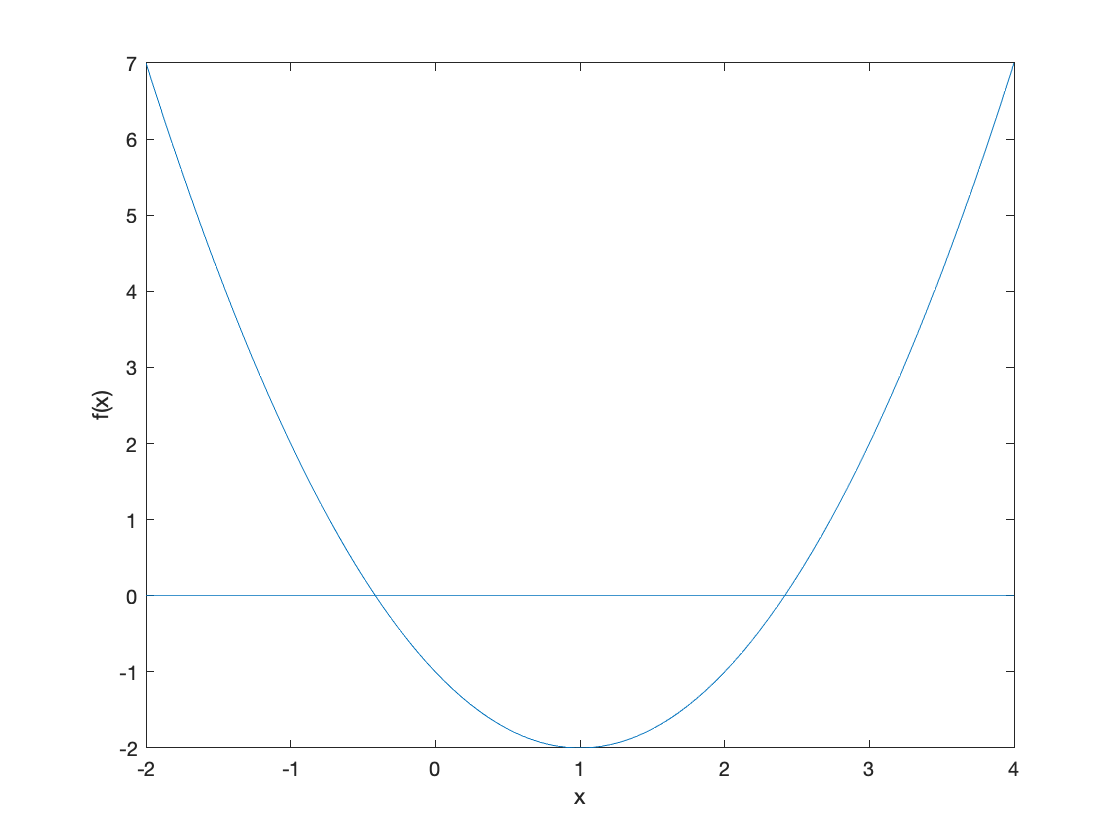

x=linspace(-2,4,100);
fx=x.*x-2*x-1;
plot(x,fx);
xlabel('x');
ylabel('f(x)');

%Plot a horizontal line at y=0 so that we can better see where the root is
y=0;
line([-2,4],[y,y])

From the graph generated, you can see that there is one root between -1 and 0 and the other root is between 2 and 3.     You should be able to use mathematical techniques to find that the roots of Eq. (5) are

                                                                            
$$x_1=1-\sqrt{2}=-0.4142135623$$


                                                                             
$$x_1=1+\sqrt{2}=2.4142135623$$


Alternatively, we could also use MATLAB, which has an inbuilt function fzero that determines the roots of a nonlinear (or linear) function by specifying a single input $\texttt{x0}$ or an interval $\texttt{[xl xu]}$.

NOTE: the input $\texttt{fun}$ has the form $\texttt{@(x) x**2-2*x-1}$, where $\texttt{@(x)}$ the is a function handle.

If we know that the function is a polynomial, MATLAB also has the function $\texttt{roots}$ whose input is a vector of the polynomial coefficients. For example if 


$$y=a_{0}+a_{1}x+a_{2}x^{2}$$


Then the input is the vector $\texttt{c = [a2 a1 a0]}$.

 Use $\texttt{roots()}$ to determine roots of Eq. (5)

roots([1 -2 -1])

ans =    -0.4142
    2.4142


Use $\texttt{fzero}$ roots of Eq. (5) that is in between $-1\leq x\leq0$

f=@(x) x.^2-2*x-1;
fzero(f,[-1 0])

ans = -0.4142

  Use $\texttt{fzero}$ to determine roots of Eq. (5) that is in between $2\leq x\leq 3$     

fzero(f,[2 3])

ans = 2.4142

What will happen if you type

fzero(f,[2])

ans = 2.4142